# 複数競技の統一的モデル：シミュレーション(1)

clear;clc;close all;

1試合を構成する小さな試合単位の数

N=20;

それぞれの得点確率

pa=0.35;
pb=0.3;
p0=1-pa-pb;
if p0<0
    disp('pa+pbは1未満としてください.');
    return
end

[aの得点確率　無得点確率　bの得点確率]

[pa p0 pb]

ans =     0.3500    0.3500    0.3000



x=1;
for n1=1:N
    x=conv(x,[pb p0 pa]);
end
xlim_min=max(find(cumsum(x)<0.001));
xlim_max=min(find(cumsum(x)>1-0.001));

figure;
tiledlayout(3,1);
nexttile([2,1]);
winMask=ones(2*N+1,1);winMask(1:N+1)=0;
drawMask=zeros(2*N+1,1);drawMask(N+1)=1;
loseMask=ones(2*N+1,1);loseMask(N+1:2*N+1)=0;
grid on;set(gca,'fontname','メイリオ');hold on;
bar(-N:N,x'.*loseMask,'BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
bar(-N:N,x'.*drawMask,'BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
bar(-N:N,x'.*winMask,'BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');
xlim(-N+[xlim_min, xlim_max]);
xlabel('得点差');
ylabel('確率')
nexttile;
plotData=[sum(x(1:N)) x(N+1) sum(x(N+2:end))]

plotData =     0.3382    0.1055    0.5562


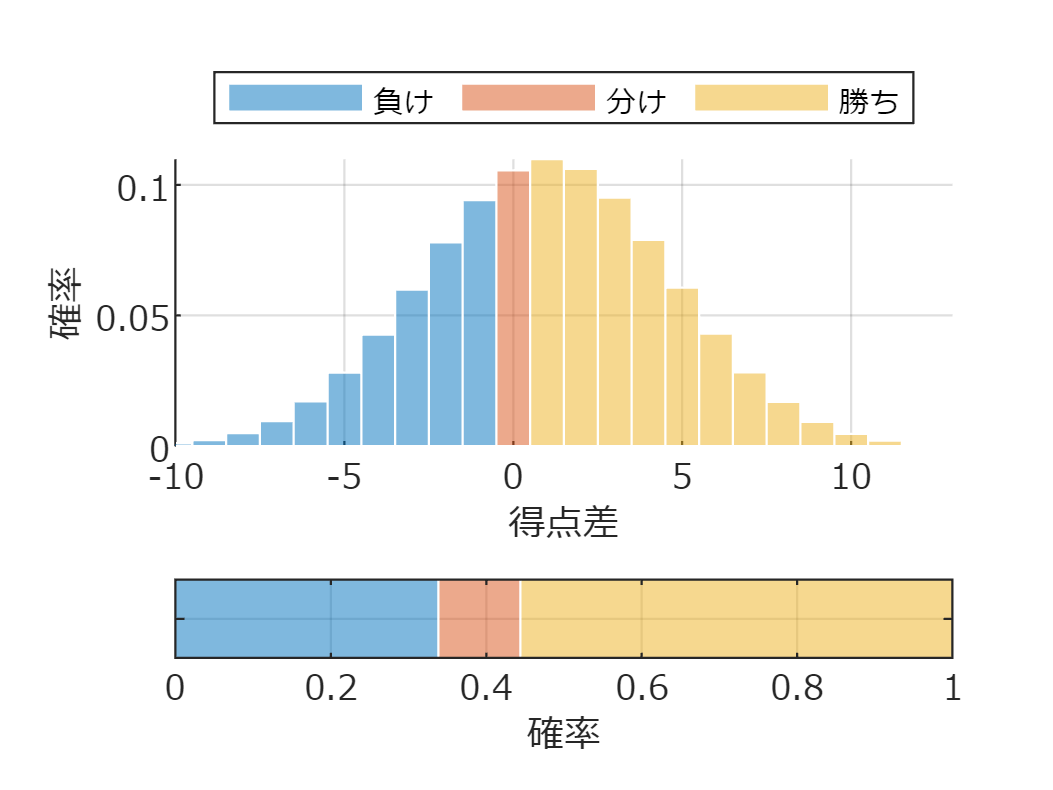

plotData=[plotData;plotData];
barh(plotData,'stacked','BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
ylim([0.5 1.5]);
grid on;set(gca,'fontname','メイリオ');hold on;
yticklabels([]);
xlabel('確率');

% exportgraphics(gcf,'fig_unifiedModelSimulation01.pdf');